%this is not a OCV chart, I would want to discharge the battery at below
%c/30 to not have a sizeable amount of voltage drop affecting the ocv

battCellData = readtable("mitCellData\VTC6_1_60_34.73_10_20181103T115614Z.csv");

battCellData(:,{'Temp1', 'Temp2', 'Temp3'}) = [];
battCellData.Time_s_ = battCellData.Time_s_(:,1) - battCellData.Time_s_(1,1);
battCellData.Power = battCellData.Volts .* battCellData.Amps;
battCellData.JoulesUsedPerStep = [0; diff(battCellData.Time_s_)] .* battCellData.Power;
battCellData.CumulativeJoules = cumsum(battCellData.JoulesUsedPerStep)

battCellData = 9887×6 table
    Time_s_     Volts        Amps         Power       JoulesUsedPerStep    CumulativeJoules
    ________    ______    __________    __________    _________________    ________________

           0    4.1897    0.00010681    0.00044751               0                   0     
    0.096806    4.1897       0.94258        3.9492          0.3823              0.3823     
     0.18941    4.1897       0.94258        3.9492         0.36573             0.74803     
     0.28981    4.1897       0.94258        3.9492         0.39647              1.1445     
     0.38978    4.0042        8.6738        34.731           3.472              4.6165     
     0.49105    4.0042        8.6738        34.731          3.5173              8.1338     
     0.59618    4.0042        8

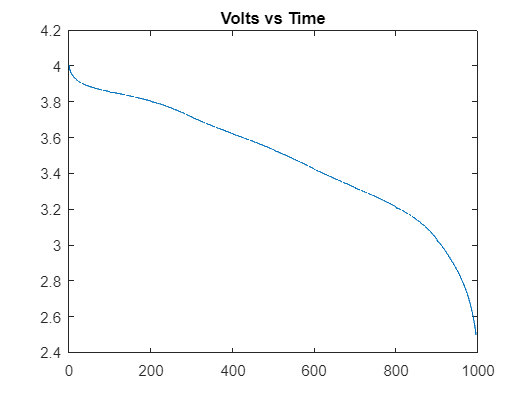

battCellData(battCellData.Power > 34.75,:) = [];
battCellData(battCellData.Power < 34.6,:) = [];
%plot(battCellData.Time_s_,battCellData.Volts);
downSampledBatt = battCellData(1:4:end,:);
plot(downSampledBatt.Time_s_, downSampledBatt.Volts)
title( 'Volts vs Time')

vtcCell10Data = table(138.*downSampledBatt.Volts, 690.*downSampledBatt.CumulativeJoules,'VariableNames',{'Volts','Energy Used'})

vtcCell10Data = 2438×2 table
    Volts     Energy Used
    ______    ___________

    552.57        3185.4 
     551.3         12974 
    550.59         22379 
    550.03         32179 
    549.13         41545 
    548.75         51476 
    548.41         60763 
    548.08         70764 
    547.78         79964 
    547.25         90489 
       547         99708 
    546.76    1.0921e+05 
    546.53    1.1846e+05 
    546.32    1.2854e+05 
    545.91    1.3789e+05 
    545.73    1.4729e+05 


exportName = 'vtc6Lookup.csv';
writetable(vtcCell10Data,exportName)




